# **Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
F:\abaqustemp\UQLab_Rel2.0.0\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - COMPUTATIONAL MODEL

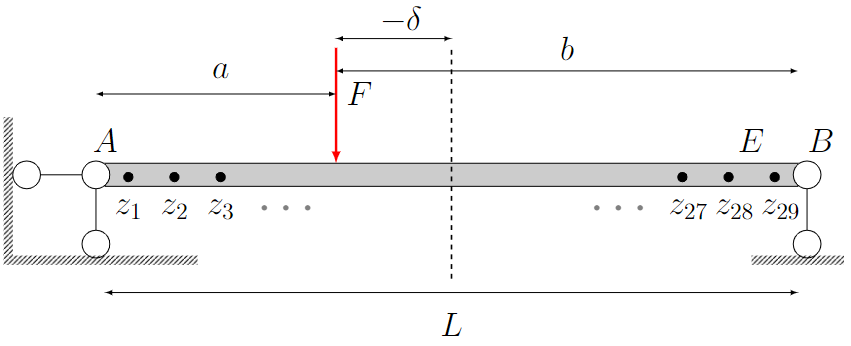

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        a = 13% distance from the point A (m)

        b = 17 % distance from the point B (m)

        L = 30; % beam length (m)

        F = 43000±10000;% Concentrated force (N)

        E = 30e9;%elastic modulus

        delta = -2; loading position

**Computational model:**

$a = \frac{L}{2}- \delta$;$b = \frac{L}{2}+ \delta$


$$\mathcal{M}(\vec{\theta}) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(\vec{\theta})  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)]}{6LEI} \ \ \ \ z> a
$$



$$\vec{\theta} = [E,\delta,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

% %LHS sampling 


% Uniform sampling 
N = 10;
p = 1;
F_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_F = -9e4;
upper_limit_F = 9e4;
F_Uniform_sample = lower_limit_F + F_lhs * (upper_limit_F - lower_limit_F);
size(F_Uniform_sample)

ans =     10     1



F = F_Uniform_sample;
size(F)

ans =     10     1


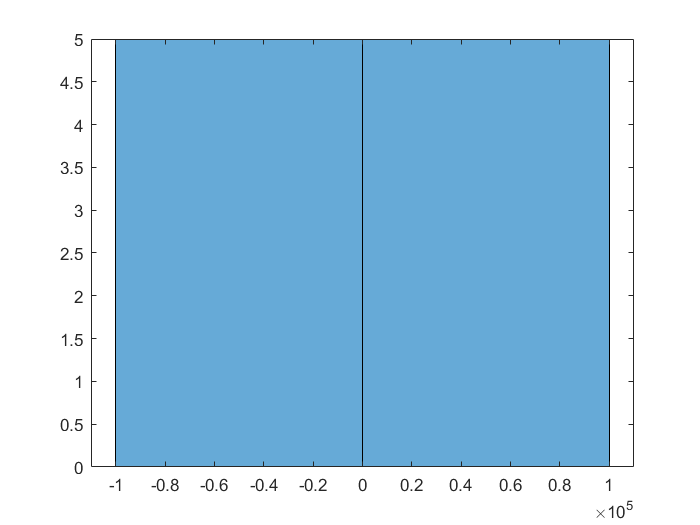

%plot uniform sampling
figure
histogram(F)

%FE realizaiton 
FE_deflection = Deflection(F);
size(FE_deflection)

ans =     10    29


FE_realization = [F_Uniform_sample,FE_deflection];
size(FE_realization)

ans =     10    30


## PCA reduce output dimensionality

%get the FE output
Y_Output = FE_realization(:,2:end);
size(Y_Output)

ans =     10    29


%define the principle numbers
N_principle = 1;
%PCA
[coeff, score, latent] = pca(Y_Output, 'NumComponents', N_principle);
%[coeff, score, ~, ~, explained, mu] = pca(Y_Output_center, 'NumComponents', N_principle);
%PCA inverse 
Y_Output_reconstructed = score * coeff' ;
size(Y_Output_reconstructed)

ans =     10    29


modelling error

PCA_loss =abs(Y_Output - Y_Output_reconstructed);
size(PCA_loss)

ans =     10    29


Cov_PCA_loss = cov(PCA_loss);
size(Cov_PCA_loss)

ans =     29    29


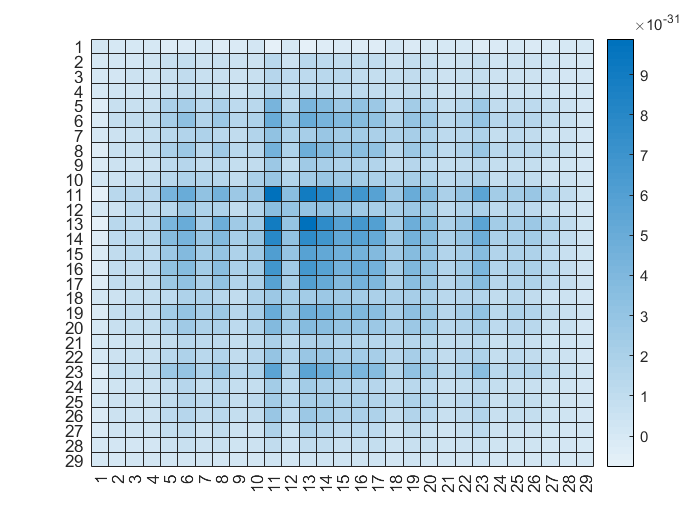

ans =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


heatmap(Cov_PCA_loss)

## 3 - PROBABILISTIC INPUT MODEL


$$F \sim \mathcal{u}(43000,10000)$$


% Young's modulus
InputOpts.Marginals(1).Type = 'Uniform';
minF = min(FE_realization(:,1));
size(minF)

ans =      1     1


maxF = max(FE_realization(:,1));
size(maxF)

ans =      1     1


InputOpts.Marginals(1).Parameters  = [minF maxF];



myInput = uq_createInput(InputOpts);

## 4 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the sparse-favouring least-square minimization LARS for the 

PCE coefficients calculation strategy:

metaopts.Method = 'LARS';

Select the PCE options and create the PCE model:

metaopts.Degree = 1:15;

Experimental design

X = FE_realization(:,1);
%Y = FE_realization(:,2:end);
Y = score;
metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 1
Final LOO error estimate: 6.777499e-32
---                 Calculation finished!                               ---


Print a summary of the resulting PCE metamodel:

uq_print(myPCE, [1])


%------------ Polynomial chaos output ------------%
   Number of input variables:    1
   Maximal degree:               1
   q-norm:                       1.00
   Size of full basis:           2
   Size of sparse basis:         2
   Full model evaluations:       10
   Leave-one-out error:          4.6011712e-32
   Modified leave-one-out error: 6.7774990e-32
   Mean value:                   1.1303
   Standard deviation:           9.8239
   Coef. of variation:           869.175%
%--------------------------------------------------%


Export the PCE strucuture

save myPCE

## 5 - Yval vs YPCE

Create a validation sample of size  from the input model:

Xval =  FE_realization(:,1);
size(Xval)

ans =     10     1


Evaluate the full model response at the validation sample points:

%Yval =  FE_realization(:,2:end);
Yval = score;
size(Yval)

ans =     10     1


Responses for PCE 

YPCE = uq_evalModel(myPCE,Xval);
size(YPCE)

ans =     10     1


True vs predicted plot

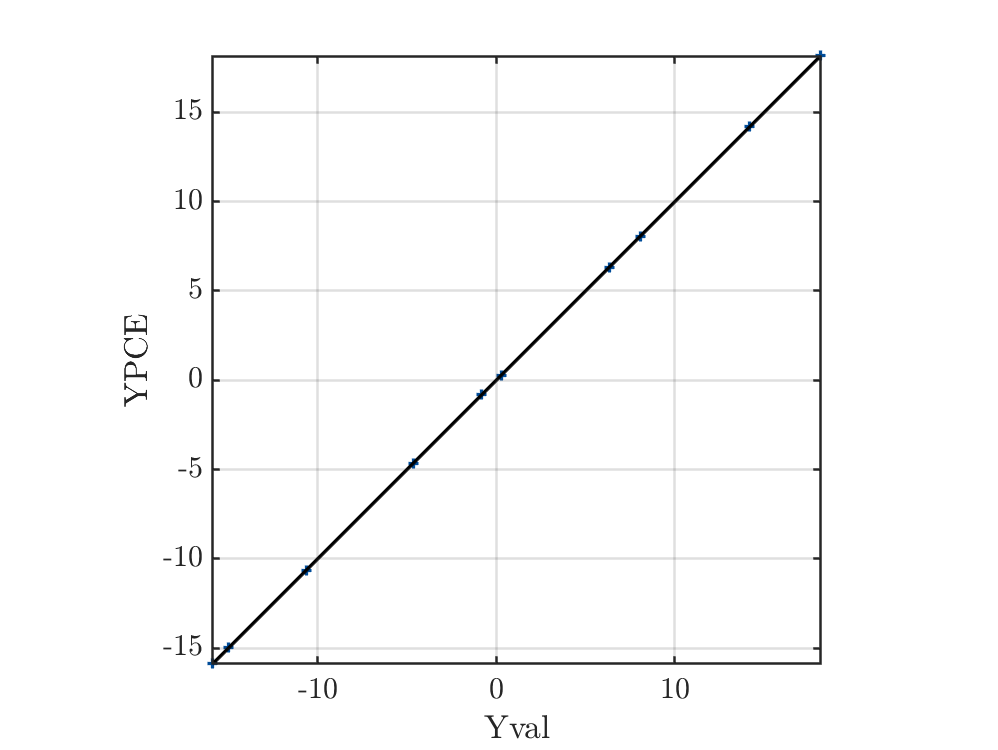

close all;
uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval,[],'all') max(Yval,[],'all')], [min(Yval,[],'all') max(Yval,[],'all')], 'k')
hold off
axis equal
axis([min(Yval,[],'all') max(Yval,[],'all') min(Yval,[],'all') max(Yval,[],'all')])
xlabel('Yval');
ylabel('YPCE');
box on;

show the covariance matrix of y_FE-output

% Output_FE_COV = cov(FE_deflection);
% heatmap(Output_FE_COV)

show the covariance matrix of PCE-output

% N_PCE = size(FE_deflection,2);
% max_len = 15;
% PCE_Coeffi_Sum = [];
% for i = 1:N_PCE
%     PCE_i_Coeffi = myPCE.PCE(i).Coefficients;
%     PCE_Coeffi = [PCE_i_Coeffi;zeros(max_len - length(PCE_i_Coeffi),1)];
%     PCE_Coeffi_Sum = [PCE_Coeffi_Sum PCE_Coeffi];
% end

Calculate the variance of PCE analytically

% PCE_Cov = [];
% for i = 1:N_PCE
%     for j = 1:N_PCE       
%         PCE_Cov(i,j) = dot(PCE_Coeffi_Sum(2:15,i),PCE_Coeffi_Sum(2:15,j));
%     end
% end
% 

show the covariance matrix of PCE

% heatmap(PCE_Cov)


## 6 - Define the priors for F and discrepancy $\sigma$

## **Note: priors for F are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

#### synthetic ground truth with 3% noise 

F = 30000N; noise = 20%

Measurement = GroundTruth(30e9,-2,30000,1,0.03);
size(Measurement)

 priors

%Priors on F
PriorOpts.Marginals(1).Name = 'F';               % Loading F
PriorOpts.Marginals(1).Type = 'Uniform';
PriorOpts.Marginals(1).Parameters = [-43000 43000];   % (N)
PriorOpts.Marginals(1).Bounds = [-9e5 9e5];

PriorOpts.Marginals(2).Name = 'Sigma2';               % Loading F
PriorOpts.Marginals(2).Type = 'Uniform';
sigma2 = mean(Measurement(:,:),"all");
PriorOpts.Marginals(2).Parameters = [0 sigma2.^2];


%define the discrepancy hyperparameters
% 
% 
% for i = 2:4
%     PriorOpts.Marginals(i).Type = 'Uniform';
%     PriorOpts.Marginals(i).Parameters = [-100 100];
% end


% PriorOpts.Marginals(5).Type = 'Uniform';
% PriorOpts.Marginals(5).Parameters = [0 5];



myPriorDist = uq_createInput(PriorOpts);
% 
% SigmaOpts.Marginals(1).Name = 'Sigma2';
% SigmaOpts.Marginals(1).Type = 'Uniform';
% sigma2 = mean(Measurement(:,:),"all");
% SigmaOpts.Marginals(1).Parameters = [0 sigma2.^2];
% 
% mySigmaDist = uq_createInput(SigmaOpts);
% DiscrepancyOptsUnknownDisc.Type = 'Gaussian';
% DiscrepancyOptsUnknownDisc.Prior = mySigmaDist;

## 7 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$



myData.y = Measurement;
size(myData.y)
myData.Name = 'Measurement on 29 points along the beam';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 8 - Solver options


Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 ];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 100;
Solver.MCMC.NChains = 5;
%Solver.MCMC.Proposal.PriorScale = 1e-3;

## 9 - Bayesian inference

%BayesOpts.Discrepancy = DiscrepancyOptsUnknownDisc;
%BayesOpts.ForwardModel.Model = myPCE;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

## 10 - Post-processing

Burn in 70%; 


badChainsIndex = squeeze(BayesAnalysis.Results.Sample(end,1,:) <-20000);

uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','mean','percentiles',[0.05,0.95],'burnin',0.7,'badChains',badChainsIndex);

uq_print(BayesAnalysis);
%uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
uq_display(BayesAnalysis);

## print the covariance

%hold off;
close all;
Mean_paramters = BayesAnalysis.Results.PostProc.Percentiles.Mean(:);
size(Mean_paramters)

calculate the autocorrelation coeficients-Matern function

h = [];% spatial length
R = [];% autocorrelation coeficients
hyper_parameters = Mean_paramters(2:9);
size(hyper_parameters)
for i  = 1:29
    for j = 1:29
                h = abs(i-j);
                if i ==j
                    R(i,j) = (1+  5^0.5*h/hyper_parameters(8)  +   5*h^2/3/hyper_parameters(8)^2)*exp(-5^0.5*h/hyper_parameters(8));

                else

                  R(i,j) = 0 ;
                end
    end
    
end

Calculate the diagonal Std


Std_covariance = [];
for i = 1:29
    xi = 2*(i-1)/(29-1) -1;
    Sum_legendre = 0;
    %summary of the legendre functions
    for j = 1:7
        Basis_legendre = legendreP(j-1,xi);
        %disp(Basis_legendre)
        Sum_legendre = Sum_legendre +  hyper_parameters(j)*Basis_legendre;
        
    end
    
    Std_covariance(i) = Sum_legendre;
    
end

Calculate the Non-diagnoal covariance


Non_diagonal_Cov = [];
for i = 1:29
    for j = 1:29
        Non_diagonal_Cov(i,j) = Std_covariance(i)*Std_covariance(j)*R(i,j);
    end
end

Print the Non-diggonal covariance

heatmap(Non_diagonal_Cov)

## 11 -  90% error band on predictive posterior

### 90% confidence interval for E and $\delta$

set 90%  = 95%- 5%


uq_postProcessInversionMCMC(BayesAnalysis,'percentiles',[0.05,0.95]);

Obtained the lower bound and upper bound for E and $\delta$

F_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
size(F_5_LowB)

F_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
size(F_95_UpperB)



N_predict = 10

% sampling on E
F_90_sample_O = linspace(F_5_LowB,F_95_UpperB,N_predict)';
size(F_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(F_90_sample_O));
F_90_sample = F_90_sample_O(shuffledIndices);
size(F_90_sample)



%plot the sampling on F
figure
histogram(F_90_sample)

Predictive FE realization

Predict_sample = [F_90_sample];
size(Predict_sample)

%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    Deflection = uq_evalModel(myPCE,Xval_Predict);
    YPCE_Predict = [YPCE_Predict;Deflection];


end

size(YPCE_Predict)

Spline curve fitting to smooth the line for the 90CI

x = 1:29;%29 measurement position along the beam

for i = 1:size(YPCE_Predict,1)
    
    P = polyfit(x,YPCE_Predict(i,:),3);
    xi = 1:0.1:29;
    YPCE_Predict_Poly(i,:) = polyval(P,xi);
end
size(YPCE_Predict_Poly)

Loop to fill the error band 90%CI

%loop to fill the error band
close all;

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [-YPCE_Predict_Poly(i,:) fliplr(-YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 ylim([-3.5 0])

scatter the measurement

x = 1:1:29;
size(x)

for i = 1: size(myData.y,1)
    scatter(x,-myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,-mean(YPCE_Predict_Poly),'red','LineWidth',1.5);

legend

rectangle('Position', [22, -2.5,0.5, 0.25], 'FaceColor', 'cyan');
text(23, -2.35, '90% CI', 'FontSize', 8);
text(22.15, -2.7, 'x  measurement points', 'FontSize', 8);

line([22,22.6],[-3,-3],'linestyle','-','color','red','LineWidth',1.0);
text(23, -3, 'mean', 'FontSize', 8);

Plot the predictive individual lines

hold off;

% beam position

x_beam = 1:1:29

for i = 1:size(YPCE_Predict,1)
    
    plot(x_beam,-YPCE_Predict(i,:));
    hold on;
end
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Predictive deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
  yticks('auto');
 ylim([-3.5 0])